# Project 3

**Name: Joshua Jackson**

**Date: 10/25/2022**

**Table of Contents:**

Problem Statement

Part I: Reorganize Equations

Part II: Compute X Using Inverse Built-in Function

Part III: Compute X Using Cramer's Rule

Part IV: Compute X Using Gauss Elimination

Part V: Compute X Using LU Decomposition

Conclusion

Discussion

Appendix

## **Problem Statement: **

A resistive circuit can be solved using mesh analysis.  

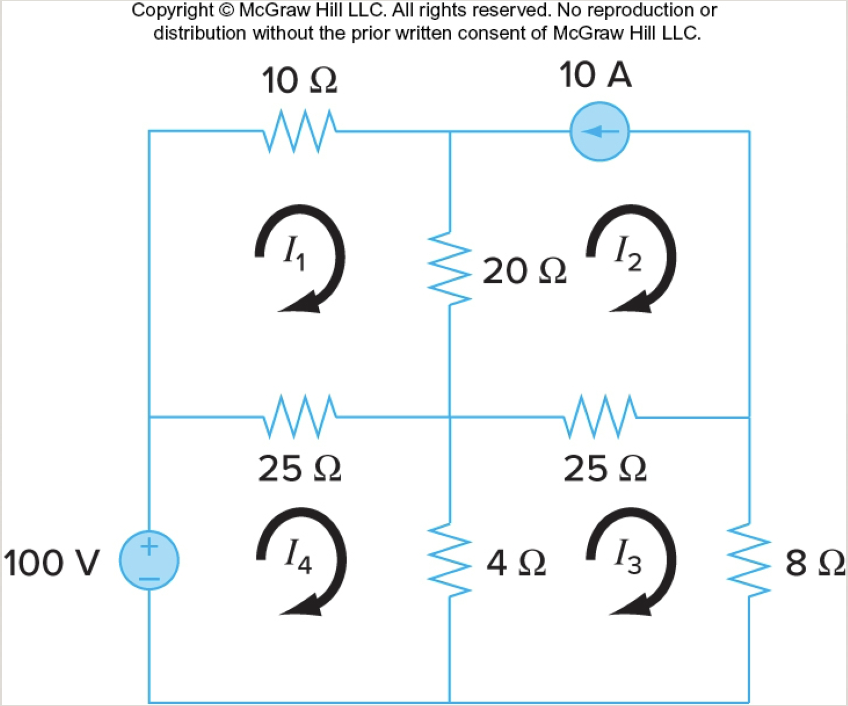

The mesh equations for the circuit above are:

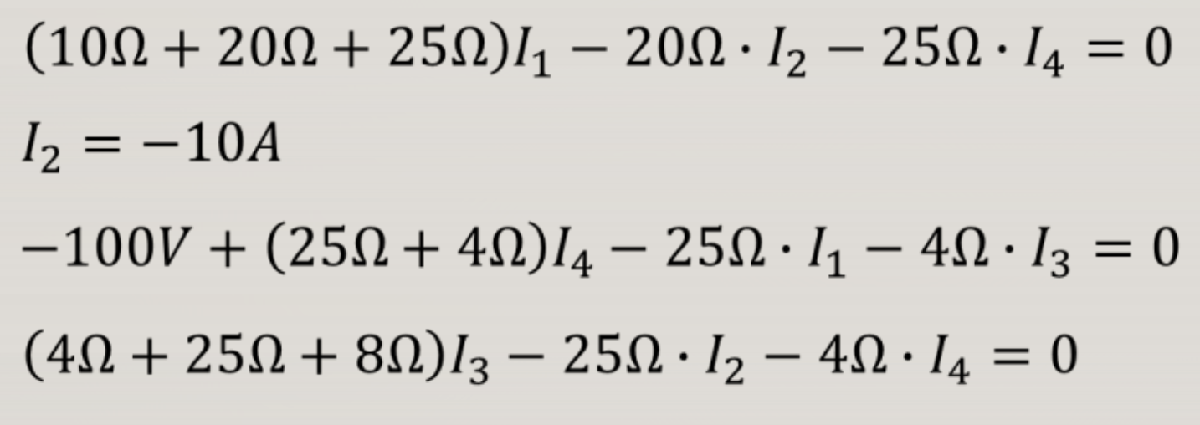

where A, V, and Ω are the units for current, voltage, and resistance respectively.

## **Part I: Reorganize Equations**

Drop the units, reorganize the equations and form a matrix equation as below: 

AX = b

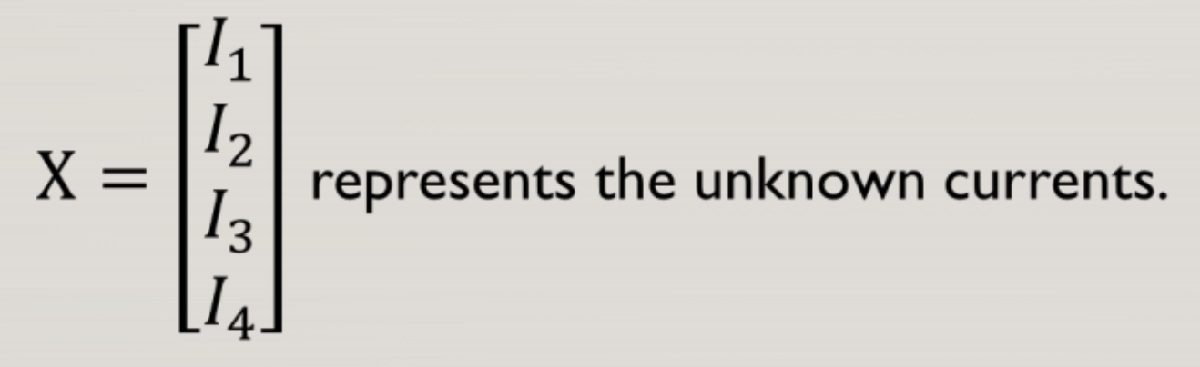

Determine the 4 by 4 square matrix A and the 4 by 1 column vector b.

A = [55 -20  0 -25;

        0     1  0   0;

      -25   0  -4  29;

        0  -25 37 -4];

b = [0 -10 100 0]'; 

## **Part II: Compute X Using Inverse Built-in Function**

Enter A and b in MATALB. Compute X using X = inv(A)*b

A = [55 -20 0 -25;
    0 1 0 0;
    -25 0 -4 29;
    0 -25 37 -4];

b = [0 -10 100 0]'; 

X = inv(A)*b

X =    -4.1103
  -10.0000
   -6.8695
   -1.0426


**Results**: By using the inverse built-in function, the results for I1, I2, I3, and I4 were found to be -4.1103 amperes, -10.0000 amperes, -6.8695 amperes, and -1.0426 amperes respectively. 

## **Part III: Compute X Using Cramer's Rule**

Use Cramer’s rule to solve X 

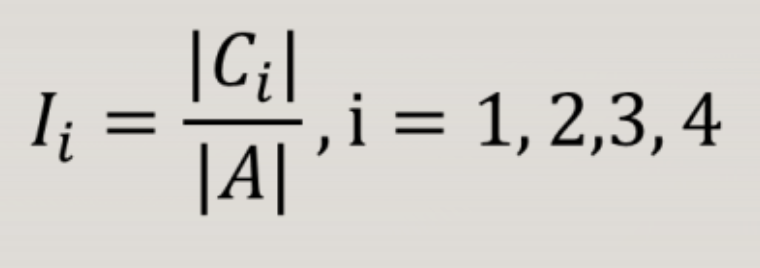

Ci is obtained by replacing the ith column in A with b. 

You may use the MATLAB built-in function det to compute the determinants

% Cramer's Rule
X = zeros(4,1);
Det_A = det(A);
for i = 1:4
    C = A;
    for j = 1:4
        C(j,i) = b(j);
    end
    Det_C = det(C);
    X(i) = Det_C/Det_A;
end
X

X =    -4.1103
  -10.0000
   -6.8695
   -1.0426


**Results**: By using Cramer's rule, the results for I1, I2, I3, and I4 were found to be -4.1103 amperes, -10.0000 amperes, -6.8695 amperes, and -1.0426 amperes respectively. When compared to the results obtained when using the inverse built-in function, these results are equal in value. 

## **Part IV: Compute X Using Gauss Elimination**

Use Gauss Elimination with partial pivoting to solve the equations, and compare the results with those from the previous steps. 

X = myGaussPivot(A, b)

X =    -4.1103
  -10.0000
   -6.8695
   -1.0426


**Results**: By using Gaussian Elimination with partial pivoting, the results for I1, I2, I3, and I4 were found to be -4.1103 amperes, -10.0000 amperes, -6.8695 amperes, and -1.0426 amperes respectively. When compared to the results obtained when using the inverse built-in function and Cramer's rule, these results are equal in value. 

## **Part V: Compute X Using LU Decomposition**

Use LU decomposition to solve the equations, and compare the results with those from the previous steps. Show the L matrix and U matrix and verify.

% perform LU decomposition
[L, U] = myLU(A)

L =     1.0000         0         0         0
         0    1.0000         0         0
   -0.4545   -9.0909    1.0000         0
         0  -25.0000   -9.2500    1.0000


U =    55.0000  -20.0000         0  -25.0000
         0    1.0000         0         0
         0         0   -4.0000   17.6364
         0         0         0  159.1364



% Verify L and U matrices (L*U=A)
A

A =     55   -20     0   -25
     0     1     0     0
   -25     0    -4    29
     0   -25    37    -4


L * U

ans =     55   -20     0   -25
     0     1     0     0
   -25     0    -4    29
     0   -25    37    -4



% obtain X by forward and backward substitution
[m,n]=size(A);
X = 0;

% for loop to perform forward substitution
for i=2:n
    sum = b(i); %Starts with b(1)
    for j=1:i-1
        sum = sum - L(i,j) * b(j);
    end
    b(i) = sum;
end

% for loop to perform backward substitution
% Normalize final row
X(m) = b(m)/U(n,m); 

for i = n-1:-1:1
    sum = 0;
    for j = i+1:m
        sum = sum + U(i,j) * X(j);
    end
    X(i) = (b(i) - sum)/U(i,i);
end

% display X
X = X'

X =    -4.1103
  -10.0000
   -6.8695
   -1.0426


**Results**: By using LU decomposition, the results for I1, I2, I3, and I4 were found to be -4.1103 amperes, -10.0000 amperes, -6.8695 amperes, and -1.0426 amperes respectively. When compared to the results obtained when using the inverse built-in function, Cramer's rule, and Gauss Elimination, these results are equal in value. 

## Conclusion

Finishing this project and computing the values of X in a varitey of ways grew my understanding of MATLAB immensely. I gained a deeper understanding of how MATLAB can be effectively used to find the unknown values in a system of equations using the MATLAB built-in inverse function, Cramer's rule, Gauss Elimination, and LU decomposition. The results of the systems of equations were computed to be -4.1103 amperes for I1, -10.0000 amperes for I2, -6.8695 amperes for I3, and -1.0426 amperes for I4. These results were consistently equal for each of the methods used to find X. As the MATLAB built-in inverse function was used to compute the values in the first trial, the determined values can be considered fairly exact and precise. Because of this, any of the 4 methods used are proficient to determine correct results. Each method has its own benefits when used in differing contexts and situations. 

One observation I had was that the LU MATLAB built-in function didn't compute the correct result. Instead, I computed the L and U matrices using the myLU function to obtain the correct results for the L and U matrices. When checked, these L and U matrices were verified to be correct as L times U equalled A. 

This project opened my eyes to the capabilities of MATLAB and I look forward to continue to grow in my knowledge of how to use MATLAB in many effective ways. 

## **Discussion**

Questions for discussion:

i) *Was pivoting in Gauss Elimination necessary for this particular problem?*

Partial pivoting in Gauss Elimination was not necessary for this particular solution. Partial pivoting in Gauss Elimination is normally used to avoid a diverging result when trying to compute X but in this particular problem, the solution using a "Naive" Gauss Elimination (without partial pivoting) does not diverge, meaning this approach to solving for X would work as well. 

ii) *In this circuit, what kind of changes (voltage source, current source, resistance, connection, etc.) will only require the forward and backward substitution steps to be repeated, but not the decomposition steps, if we solve the equations using LU decomposition? *

In this circuit, changes in the voltage source and the current source will only require the forward and backward substitution steps to be repeated. This is because the voltage and currents are constant variables (not multiplied by the I values) as they are the values that appear in the b vector when solving the system of equations. Any change in the A matrice would require the decomposition steps to be taken when computing the solution for the system through LU decomposition. Changes in the resistance and connection would force changes to occur with the variables that are being multiplied by the I values or would change the sign of the I values which would mean they would be included in the A matrix would consequently require the decomposition steps to be computed. 

iii) *Since we already know that I2 = -10A by inspection, we can plug it into the other equations and then only solve three linear algebraic equations with three unknowns. How to implement this improvement with MATLAB in a generic way? (You just need to describe your idea.)*

Since we already know that I2 = -10A, I would implement this improvement in a generic way by starting with reforming the A matrix and b vectors. I would do this by plugging in -10A for I2 in equations 1, 3, and 4, and perform additions or subtractions in equations 1, 3, and 4 until the unknown values were on the left and the known values were on the right side of the equation. Next, I would determine A (a now 3x3 matrix), and b (a now 3x1 vector) from this new set of equations. 

I would then progress through each part to determine the values of I1, I3, and I4, making minute changes to the code where needed. The built-in function would not need to be changed, but the initialized X matrix in Cramer's rule would need to change from 4x1 to 3x1 and both i and j (the assigned row and column values) would need to progress from 1 to 3 rather than 1 to 4. Both the Gauss Elimination function, and the LU decomposition code and function would work with the new A matrix and b vector, so no changes would need to be made there. With the known value of I2 and these simple adjustments, I1, I3, and I4 can all be determined. 

## Appendix

#### Function used to compute X with Gaussian Elimination

function x = myGaussPivot(A,b)
% myGaussPivot: improved Gauss elimination by partial pivoting
% switching the rows so that the largest element is the pivot element.
% input:
%   A = coefficient matrix
%   b = right hand side vector
% output:
%   x = solution vector
    [m,n] = size(A);
    if m~=n
        error('Matrix A must be square'); 
    end
    nb=n+1;
    Aug=[A b];
    % forward elimination
    for k = 1:n-1
       
        %partial pivoting
        [big, i] = max(abs(Aug(k:n,k)));
        ipr = i + k - 1;
        if ipr~=k
            Aug([k,ipr],:) = Aug([ipr,k],:);
        end
        
        for i = k+1:n
            factor=Aug(i,k)/Aug(k,k);
            Aug(i,k:nb)=Aug(i,k:nb)-factor*Aug(k,k:nb);
        end
    end
    % back substitution
    x=zeros(n,1);
    x(n)=Aug(n,nb)/Aug(n,n);
    for i = n-1:-1:1
      x(i)=(Aug(i,nb)-Aug(i,i+1:n)*x(i+1:n))/Aug(i,i);
    end
end

#### Function Used to compute X with LU decomposition

function [L, U] = myLU(A)
% myLU: LU decomposition 
% input:
%   A = a square matrix
% output:
%   L = Lower triangular matrix
%   U = Upper triangular matrix
    [m,n] = size(A);
    if m~=n
        error('Matrix A must be square'); 
    end
    for k = 1:n-1
      for i = k+1:n
        factor = A(i,k)/A(k,k);
        A(i,k) = factor;
        for j = k+1:n
            A(i,j) = A(i,j)-factor*A(k,j);
        end
       end
    end
    for k=1:n
        L(k,1:k-1)=A(k,1:k-1);
        L(k,k)=1;
        L(k,k+1:n)=0;
        U(k,1:k-1)=0;
        U(k,k:n)=A(k,k:n);
    end 
end